# HW 4: Linear Regression 

Work done with the help of ChatGPT: [https://chat.openai.com/share/e982f652-75f9-4d7a-a6ed-944e65be73bf](https://chat.openai.com/share/e982f652-75f9-4d7a-a6ed-944e65be73bf) 

Using the following data set to investigate the relationship between Age and Wing Length, and use the data to generate answers to the prompts below:

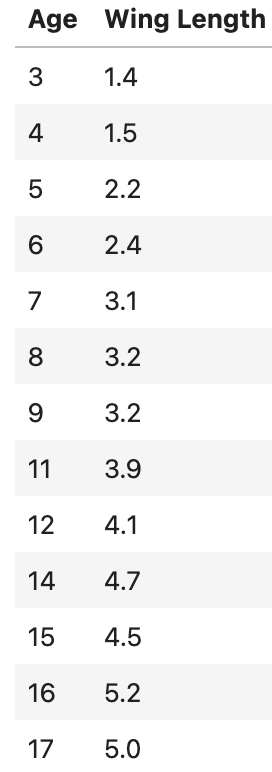

1. Plot the relationship between Age and Wing Length.

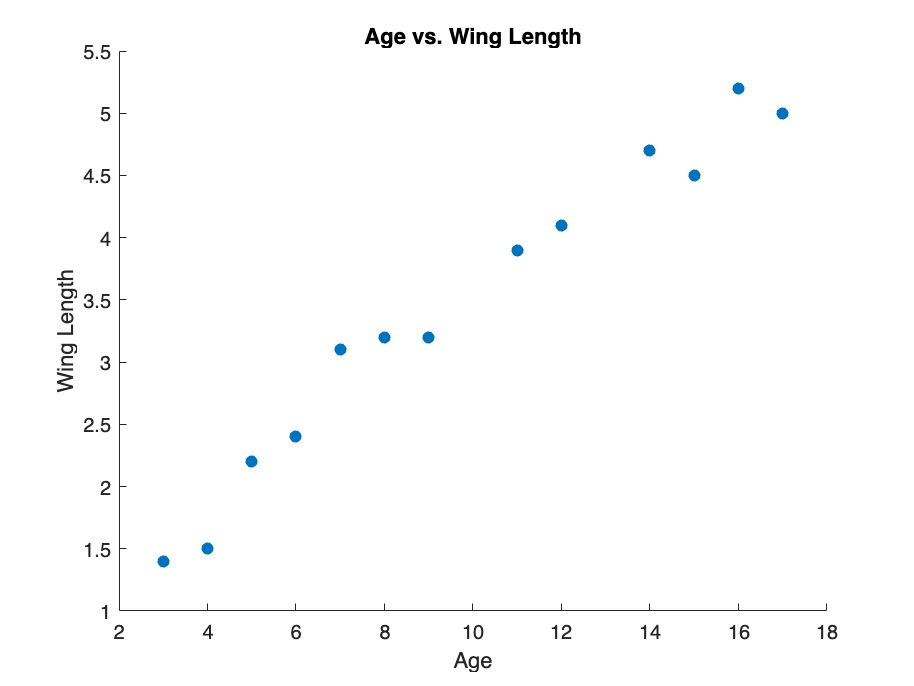

% Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Create a scatter plot

scatter(Age, WingLength, 'filled'); % 'filled' fills the markers

% Add labels and title
xlabel('Age');
ylabel('Wing Length');
title('Age vs. Wing Length');

2. Calculate and plot the regression line.

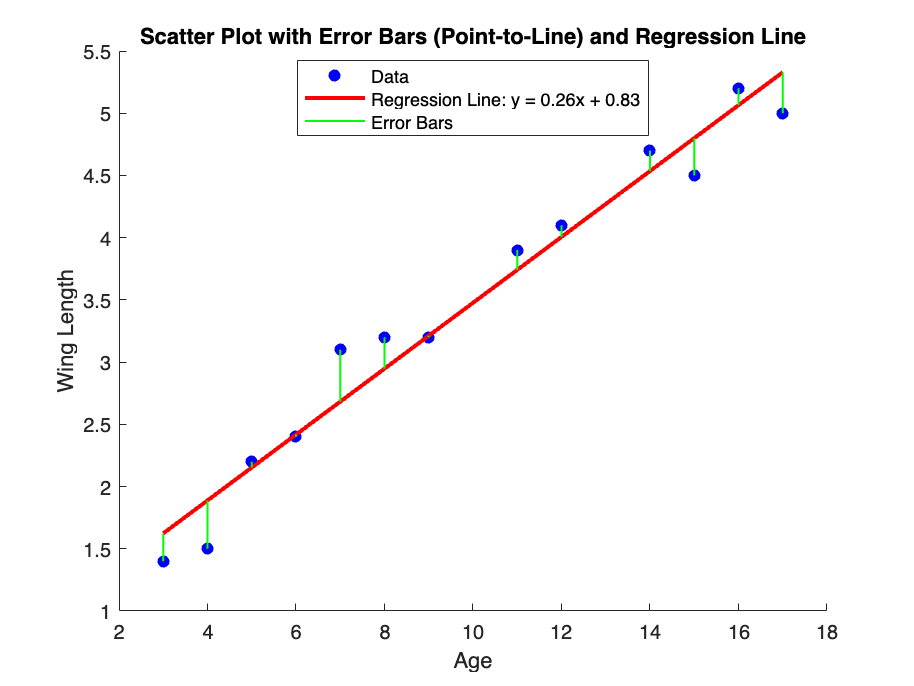

% Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Fit a linear regression model
coefficients = polyfit(Age, WingLength, 1);

% Extract the coefficients
slope = coefficients(1);
intercept = coefficients(2);

% Calculate the error bars as the difference between points and regression line
errors = WingLength - (slope * Age + intercept);

% Create a scatter plot with different colors
scatter(Age, WingLength, 'b', 'filled'); % Blue scatter points

hold on; % Hold the current plot

% Plot the regression line using the equation in red
x_fit = min(Age):0.1:max(Age); % Create a range of x values for the line
y_fit = slope * x_fit + intercept; % Calculate corresponding y values
plot(x_fit, y_fit, 'r', 'LineWidth', 2); % Red regression line

% Plot error bars as lines connecting the points to the regression line
for i = 1:length(Age)
    plot([Age(i), Age(i)], [WingLength(i), slope * Age(i) + intercept], 'g', 'LineWidth', 1);
end

hold off; % Release the plot

% Add labels, title, and display coefficient values
xlabel('Age');
ylabel('Wing Length');
title('Scatter Plot with Error Bars (Point-to-Line) and Regression Line');

% Display the coefficient values
legend('Data', sprintf('Regression Line: y = %.2fx + %.2f', slope, intercept), 'Error Bars', 'Location', 'Best');

3. Can you reject Ho: b=0? 

% Calculate the Pearson correlation coefficient
[r, p] = corr(Age', WingLength', 'Type', 'Pearson');

% Display the correlation coefficient and p-value
fprintf('Pearson Correlation Coefficient (r): %.4f\n', r);

Pearson Correlation Coefficient (r): 0.9815


fprintf('P-value: %.4f\n', p);

P-value: 0.0000



% Set significance level (e.g., alpha = 0.05)
alpha = 0.05;

% Test for significance
if p < alpha
    fprintf('Reject the null hypothesis. There is a significant correlation between age and wing length.\n');
else
    fprintf('Fail to reject the null hypothesis. There is no significant correlation between age and wing length.\n');
end

Reject the null hypothesis. There is a significant correlation between age and wing length.


4. Calculate and plot the confidence intervals on the slope of the regression.

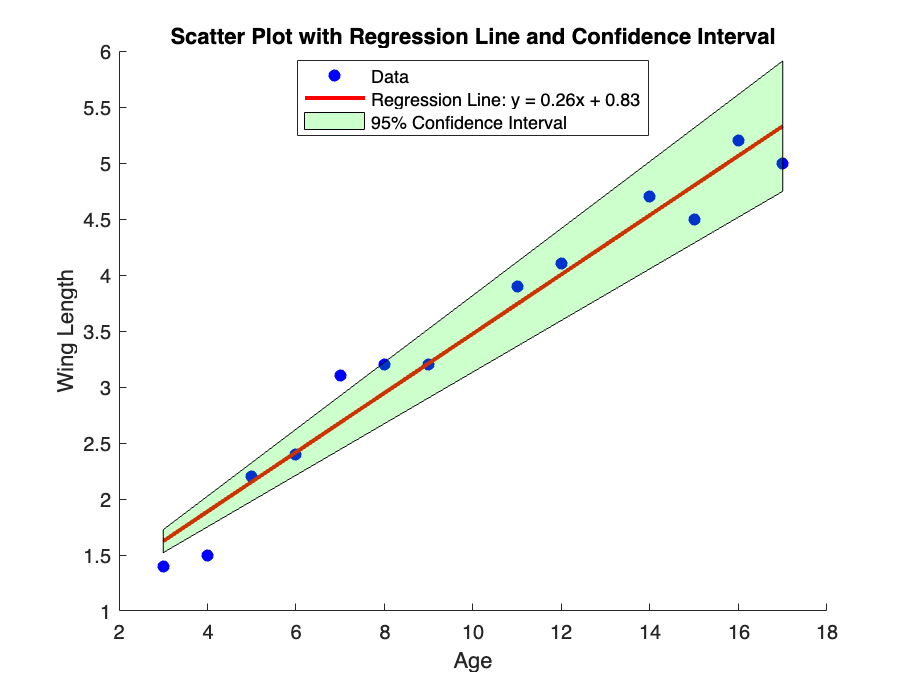

% Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Fit a linear regression model
coefficients = polyfit(Age, WingLength, 1);

% Extract the coefficients
slope = coefficients(1);
intercept = coefficients(2);

% Calculate the standard error of the estimate
residuals = WingLength - (slope * Age + intercept);
std_error = sqrt(sum(residuals.^2) / (length(Age) - 2));

% Calculate the t-statistic for a 95% confidence interval
t_critical = tinv(0.975, length(Age) - 2);

% Calculate the margin of error
margin_error = t_critical * (std_error / sqrt(sum((Age - mean(Age)).^2)));

% Calculate confidence intervals for the regression line
slope_lower = slope - margin_error;
slope_upper = slope + margin_error;

% Create a scatter plot
figure(3)
scatter(Age, WingLength, 'b', 'filled'); % Blue scatter points
hold on; % Hold the current plot

% Plot the regression line using the equation in red
x_fit = min(Age):0.1:max(Age); % Create a range of x values for the line
y_fit = slope * x_fit + intercept; % Calculate corresponding y values
plot(x_fit, y_fit, 'r', 'LineWidth', 2); % Red regression line

% Plot the shaded confidence interval region
fill([x_fit, fliplr(x_fit)], [slope_lower * x_fit + intercept, fliplr(slope_upper * x_fit + intercept)], 'g', 'FaceAlpha', 0.2);

hold off; % Release the plot

% Add labels, title, and display coefficient values
xlabel('Age');
ylabel('Wing Length');
title('Scatter Plot with Regression Line and Confidence Interval');

% Display the coefficient values and confidence interval
legend('Data', sprintf('Regression Line: y = %.2fx + %.2f', slope, intercept), ...
    '95% Confidence Interval', 'Location', 'Best');


% Optional: Adjust axis limits if needed
% xlim([min(Age) - 1, max(Age) + 1]);
% ylim([min(WingLength) - 1, max(WingLength) + 1]);


4. Calculate r^2 (the coefficient of determination)

% Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Fit a linear regression model
coefficients = polyfit(Age, WingLength, 1);

% Extract the coefficients
slope = coefficients(1);
intercept = coefficients(2);

% Calculate the predicted values
predicted = slope * Age + intercept;

% Calculate the total sum of squares (TSS)
mean_WingLength = mean(WingLength);
TSS = sum((WingLength - mean_WingLength).^2);

% Calculate the residual sum of squares (RSS)
RSS = sum((WingLength - predicted).^2);

% Calculate R^2
R_squared = 1 - (RSS / TSS);

fprintf('R^2 (Coefficient of Determination): %.4f\n', R_squared);

R^2 (Coefficient of Determination): 0.9634


6. Calculate Pearson's *r*.

% Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Calculate Pearson's correlation coefficient (r) manually (sample correlation)
n = length(Age); % Number of data points

% Calculate means
mean_Age = mean(Age);
mean_WingLength = mean(WingLength);

% Calculate covariance (sample covariance)
covariance = sum((Age - mean_Age) .* (WingLength - mean_WingLength)) / (n - 1);

% Calculate sample standard deviations
std_Age = sqrt(sum((Age - mean_Age).^2) / (n - 1));
std_WingLength = sqrt(sum((WingLength - mean_WingLength).^2) / (n - 1));

% Calculate Pearson's correlation coefficient (sample correlation)
r = covariance / (std_Age * std_WingLength);

fprintf("Pearson's Correlation Coefficient (r): %.4f\n", r);

Pearson's Correlation Coefficient (r): 0.9815


7. Add some noise to the data and see how the regression changes.

% Original Data
Age = [3, 4, 5, 6, 7, 8, 9, 11, 12, 14, 15, 16, 17];
WingLength = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Adding more random noise to make it noisier
rng('default'); % For reproducibility
noise = 0.5 * randn(size(WingLength)); % Increased noise level
NoisyWingLength = WingLength + noise;

% Fit a linear regression model to the original data
original_coefficients = polyfit(Age, WingLength, 1);
original_slope = original_coefficients(1);
original_intercept = original_coefficients(2);

% Fit a linear regression model to the noisy data
noisy_coefficients = polyfit(Age, NoisyWingLength, 1);
noisy_slope = noisy_coefficients(1);
noisy_intercept = noisy_coefficients(2);

% Calculate predicted values for both original and noisy data
original_predicted = original_slope * Age + original_intercept;
noisy_predicted = noisy_slope * Age + noisy_intercept;

% Calculate residuals for both data sets
original_residuals = WingLength - original_predicted;
noisy_residuals = NoisyWingLength - noisy_predicted;

% Confidence level for confidence intervals
confidence_level = 0.95;

% Calculate standard error of the estimate for both data sets
original_std_error = std(original_residuals) / sqrt(length(Age));
noisy_std_error = std(noisy_residuals) / sqrt(length(Age));

% Calculate t-statistic for confidence intervals
t_critical = tinv(1 - (1 - confidence_level) / 2, length(Age) - 2);

% Calculate margin of error for both data sets
original_margin_error = t_critical * original_std_error;
noisy_margin_error = t_critical * noisy_std_error;

% Calculate confidence intervals for the original and noisy data
original_conf_interval = [original_slope - original_margin_error, original_slope + original_margin_error];
noisy_conf_interval = [noisy_slope - noisy_margin_error, noisy_slope + noisy_margin_error];

% Create the first plot for the original data
subplot(2, 1, 1);
scatter(Age, WingLength, 'b', 'filled'); % Blue scatter points for original data
hold on; % Hold the current plot

% Plot the regression line for the original data in red
x_fit = min(Age):0.1:max(Age); % Create a range of x values for the line
original_y_fit = original_slope * x_fit + original_intercept; % Calculate corresponding y values
plot(x_fit, original_y_fit, 'r', 'LineWidth', 2); % Red regression line for original data

% Plot confidence interval as a shaded region for the original data
fill([x_fit, fliplr(x_fit)], [original_conf_interval(1) * x_fit + original_intercept, fliplr(original_conf_interval(2) * x_fit + original_intercept)], 'm', 'FaceAlpha', 0.2);

hold off; % Release the plot

% Add labels, title, and display coefficient values for the original data
xlabel('Age');
ylabel('Wing Length');
title('Original Data with Regression Line, Error Bars, and Confidence Interval');

fprintf('Slope for Original Data: %.4f\n', original_slope);

Slope for Original Data: 0.2647


fprintf('Intercept for Original Data: %.4f\n', original_intercept);

Intercept for Original Data: 0.8296



% Create the second plot for the noisy data
subplot(2, 1, 2);
scatter(Age, NoisyWingLength, 'b', 'filled'); % Blue scatter points for noisy data
hold on; % Hold the current plot

% Plot the regression line for the noisy data in green
noisy_y_fit = noisy_slope * x_fit + noisy_intercept; % Calculate corresponding y values
plot(x_fit, noisy_y_fit, 'g', 'LineWidth', 2); % Green regression line for noisy data

% Plot confidence interval as a shaded region for the noisy data
fill([x_fit, fliplr(x_fit)], [noisy_conf_interval(1) * x_fit + noisy_intercept, fliplr(noisy_conf_interval(2) * x_fit + noisy_intercept)], 'c', 'FaceAlpha', 0.2);

hold off; % Release the plot

% Add labels, title, and display coefficient values for the noisy data
xlabel('Age');
ylabel('Noisy Wing Length');
title('Noisy Data with Regression Line, Error Bars, and Confidence Interval');

fprintf('Slope for Noisy Data: %.4f\n', noisy_slope);

Slope for Noisy Data: 0.3244


fprintf('Intercept for Noisy Data: %.4f\n', noisy_intercept);

Intercept for Noisy Data: 0.5791


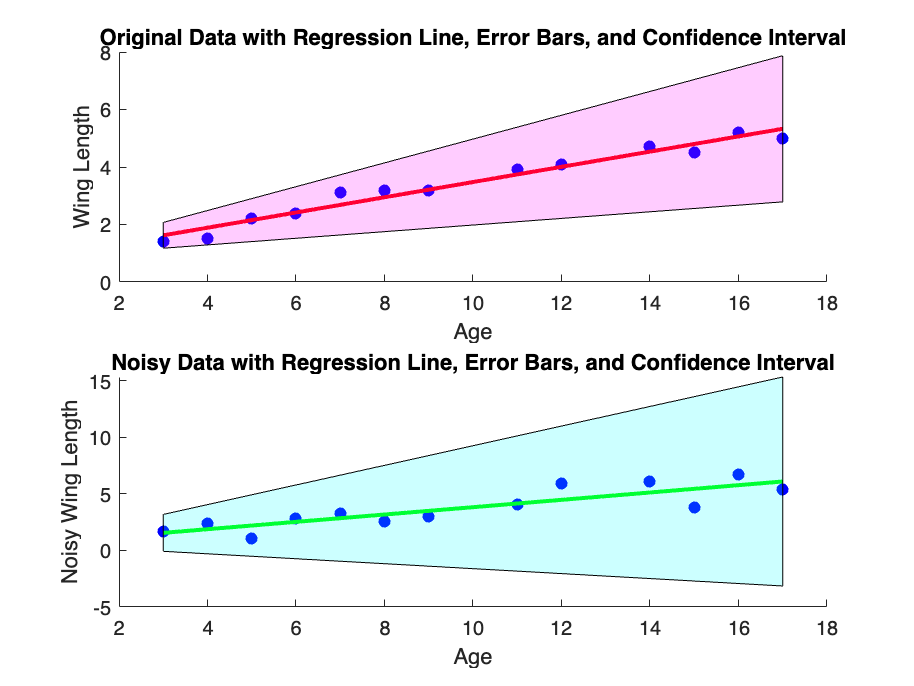


% Adjust the subplot layout
subplot(2, 1, 1);